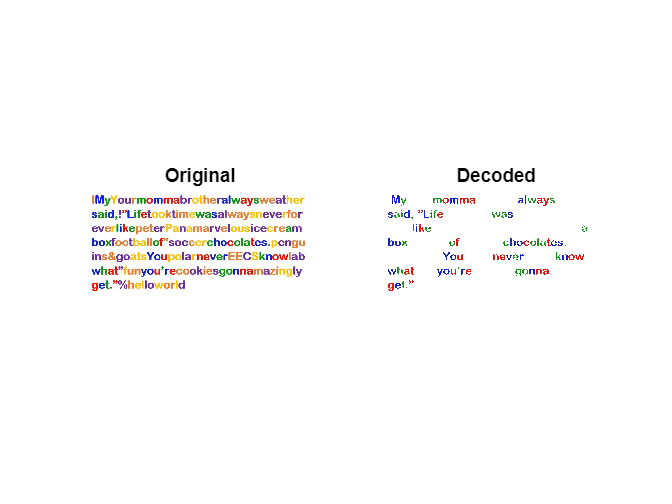

% Exercise 2 : Find the hidden message
% Read the image
img = imread('color_code_rgb.jpg');

% Create arrays for RGB
r = img(:,:,1);
g = img(:,:,2);
b = img(:,:,3);

threshold = 3;

% either one of the conditions must be met, otherwise the output looks too bright
mask = r > threshold * g & r > threshold * b | g > threshold * r & g > threshold * b | b > threshold * r & b > threshold * g;

% Combine the masks into a 3D one
color_filter = cat(3, mask, mask, mask);

% Apply the color filter to the image
pic_decoded = img;
pic_decoded(~color_filter) = 255; % Set non-RGB pixels to white

% Display the image
subplot(1,2,1);
imshow(img);
title("Original");

subplot(1,2,2);
imshow(pic_decoded);
title("Decoded");


% Save the image
imwrite(pic_decoded, 'color_decoded.jpg');